## How to properly tweak envelopes

### The ABC

Focus on the attack first, since the decay and release curves are "inverted" attack, with a range.

Need to define a clean attack that leverages from few micro-secronds (the *anti-glitch* minimum time) to 10 seconds.

In this document we will consider:

- A sampling frequency of 48kHz

- A minimum attack equal to 10 samples

- A maximum duration attack of 10 seconds

sampling_freq = 48000

sampling_freq = 48000

amin = 10;
amax = 10 * sampling_freq;

Need to design a clean attack envelope, with respect to ear's perception, which is basically logarithmic.

The raw curve is given by the *cincr* function, that increments the amplitude at every tick:


$$A=A_{\max } \;\left(1-e^{-\;\frac{t}{T}} \right)$$


Where:

- $A_{\max } \;$is the maximum amplitude (i.e. 1 for an attack if the volume leverages from 0 to 1

- $t$is the current tick, from 0 to the duration (in samples) of the attack (named *atk* in this study)

- $T$ defines the *aggressivity* of the curve, the lower the more aggressive

Intuitively, for very short attacks, we need a very low value for $T$ and a much bigger for slow attacks:


$$T=\phi \left(\mathrm{atk}\right)$$


function y = cincr0(t, tau, amax)
    y = single(amax * (1 - exp(-t/tau)));
end

For example, given $\phi \left(x\right)=x$, the attack curve for the minimum, half of the maximum and maximum attack value:

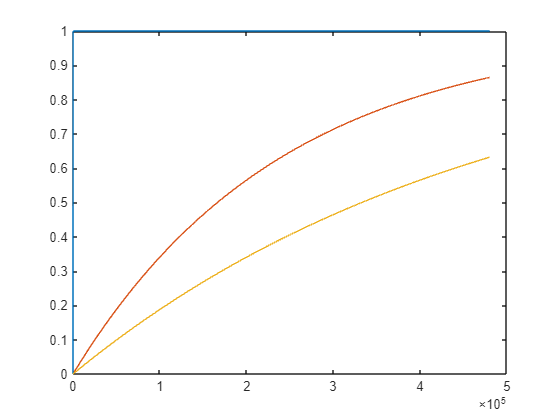

ticks = linspace(0, atk, atk);
atk = amin;
amplitude_amin = cincr0(ticks, atk, 1);
atk = amax/2;
amplitude_amax2 = cincr0(ticks, atk, 1);
atk = amax;
amplitude_amax = cincr0(ticks, atk, 1);

xlabel('tick');
ylabel('amplitude');
plot(ticks, amplitude_amin, ticks, amplitude_amax2, ticks, amplitude_amax);

Clearly, the figure above shows that $T=\phi \left(\mathrm{atk}\right)$ is not a good choice: for long attacks, the curve is to "linear" and does not reach the expected maximum.

### Perceptive considerations

Considering ampitudes in this scope implies thinking in subtracting decibels rather than adding. In other words, an amplitude of 1 is the maximum volume that can be reached, whereas 0 means "removing enough dB to get an unperceptible sound".

Empirically, **-40dB** is a good threshold to consider that the output is almost silent.

We want to get attacks that:

- Grow very fast at the beggining

- Become much flatter when reaching the asymptotic value of 1

We may consider **-6dB** and **-3dB** as well-known remarkable points to tune the attack curve.